**EE-414 Speech Processing Lab**

**Lab-8**

**AIM**

- To understand motivation behind Cepstral Analysis of speech

- To understand basic Cepstral Analysis approach

- To perform vocal tract and source information separation by Cepstral Analysis

- To understand liftering concept in cepstral Analysis

- To develop a pitch determination method by Cepstral analysis.

- To develop a formant information determination method by Cepstral analysis.

**THEORY**

Speech is composed of excitation source and vocal tract system components. In order to analyze and model the excitation and system components of the speech independently and also use that in various speech processing applications, these two components have to be separated from the speech. **The objective of *****cepstral analysis***** is to separate the speech into its source and system components without any a priori knowledge about source and / or system.**

According to the source filter theory of speech production, voiced sounds are produced by exciting the time varying system characteristics with periodic impulse sequence and unvoiced sounds are produced by exciting the time varying system with a random noise sequence. The resulting speech can be considered as the convolution of respective excitation sequence and vocal tract filter characteristics. If e(n) is the excitation sequence and h(n) is the vocal tract filter sequence, then the speech sequence s(n) can be expressed as follows:

The speech sequence has to be deconvolved into the excitation and vocal tract components in the time domain. For this, multiplication of the two components in the frequency domain has to be converted to a linear combination of the two components. For this purpose cepstral analysis is used for transforming the multiplied source and system components in the frequency domain to linear combination of the two components in the cepstral domain.

**PROCEDURE**

Record (16kHz, 16bit) the word “**speech signal**”; truncate long silence regions. 

**a) Fundamentals of cepstral analysis of speech:**

**THEORY :**

1) Log operation transforms the magnitude speech spectrum where the excitation component and vocal tract component are multiplied, to a linear combination (summation) of these components i.e. log operation converted the "*" operation into "+" operation in the frequency domain.

 2) ***The separation can be done by taking the inverse discrete fourier transform (IDFT) of the linearly combined log spectra of excitation and vocal tract system components.*** ( IDFT of linear spectra transforms back to the time domain but the IDFT of log spectra transforms to *quefrency* domain or the cepstral domain which is similar to time domain. )  

3)  In the quefrency domain the **vocal tract components are represented by the slowly varying components** concentrated near the lower quefrency region and **excitation components are represented by the fast varying components **at the higher quefrency region.

4) Procedure to calculate Cepstrum:

 

- Select a frame (20 ms long) at the centre of a voiced segment. Plot the time waveform, the log-magnitude spectrum, and the cepstrum.. 

-  Repeat the above for an unvoiced segment.

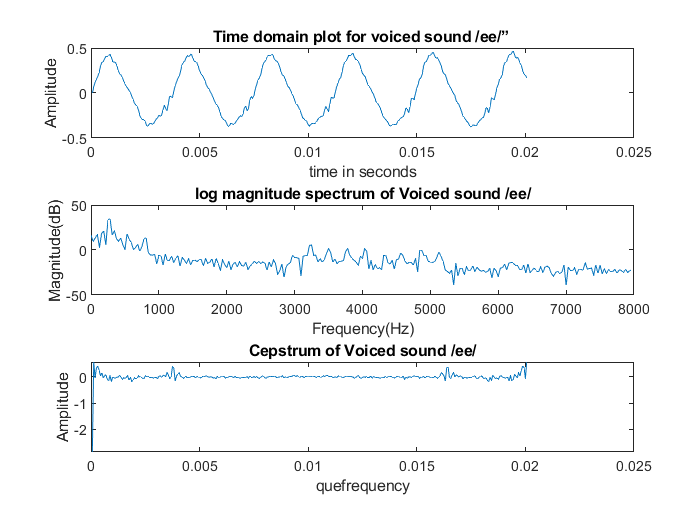

%Voiced 'ee' segment from "speech signal"
y_ee = y(ceil(1.058*fs:1.078*fs));
%UnVoiced 's' segment from "speech signal"
y_ss = y(ceil(0.445*fs:0.465*fs));

t_ee = (1:length(y_ee))/fs;
t_s = (1:length(y_ss))/fs;

%ploting time domain plot for voiced segment /ee/
figure ;
subplot(3,1,1)
plot(t_ee,y_ee);
xlabel('time in seconds');
ylabel('Amplitude');
title('Time domain plot for voiced sound /ee/” ')

%plotting log-magnitude spectrums
%for voiced sound /ee/
[freq,Y] = mag_spec(y_ee,fs);

subplot(3,1,2)
plot(freq,20*log10(abs(Y)))
title('log magnitude spectrum of Voiced sound /ee/');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');

%plotting cepstrum 
%for voiced sound /ee/
N = 160;
y1_ee = y_ee.*hamming(length(y_ee));
y_ee_cep = ifft(log(abs(fft(y1_ee))));
subplot(3,1,3)
plot(t_ee,y_ee_cep)
title( 'Cepstrum of Voiced sound /ee/');
xlabel('quefrequency');
ylabel('Amplitude');

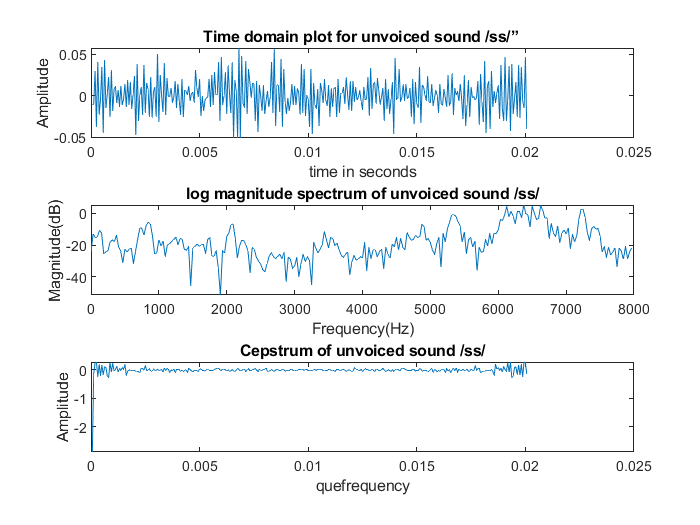

%ploting time domain plot for Unvoiced
figure ;
subplot(3,1,1)
plot(t_s,y_ss);
xlabel('time in seconds');
ylabel('Amplitude');
title('Time domain plot for unvoiced sound /ss/” ')

%plotting log-magnitude spectrums
%for voiced sound /ee/
[freq,Y] = mag_spec(y_ss,fs);

subplot(3,1,2)
plot(freq,20*log10(abs(Y)))
title('log magnitude spectrum of unvoiced sound /ss/');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');

%plotting cepstrum 
%for unvoiced sound /ss/
y1_ss = y_ss.*hamming(length(y_ss));
y_ss_cep = ifft(log(abs(fft(y1_ss))));
subplot(3,1,3)
plot(t_s,y_ss_cep)
title( 'Cepstrum of unvoiced sound /ss/');
xlabel('quefrequency');
ylabel('Amplitude');

**Observations:**

-  It can be observed that vocaltract components are concentrated in the low quefrency region and excitation components are in the high quefrency region

3. Write the procedure to determine whether the segment is voiced/unvoiced by inspecting the cepstrum. Apply this procedure to the two segments (in a and b).

Procedure to determine if the segment is voiced/unvoiced:

By inspection,

- The cepstrum of voiced sound has a small peak in the high quefrency value.

- The first cepstral coefficient of voiced segment is higher than unvoiced segments.

By inspecting these charasteristics in above two segments, voiced and unvoiced segments can be easily determined.

**B. Liftering:**

**Theory:**

Methods have  to be devised to extract to these vocal tract and excitation characteristics independently. For this purpose a ***liftering*** operation is performed in the quefrency domain.

***Liftering*** operation is similar to filtering operation in the frequency domain where a desired quefrency region for analysis is selected by multiplying the whole cepstrum by a rectangular window at the desired position. 

There are two types of liftering performed:

1) low-time liftering : extract the vocal tract characteristics in the quefrency domain 

2) high-time liftering: extract the excitation characteristics of the analysis speech frame.

**PROCEDURE:**

- Extract the deconvolved vocal tract component and excitation component from the cepstrum by liftering.

%low-time liftering
y_ee_lift=y_ee_cep(1:length(y_ee_cep)/2);%as cepstrum is symmetric we are taking half of the cepstral coefficiets 

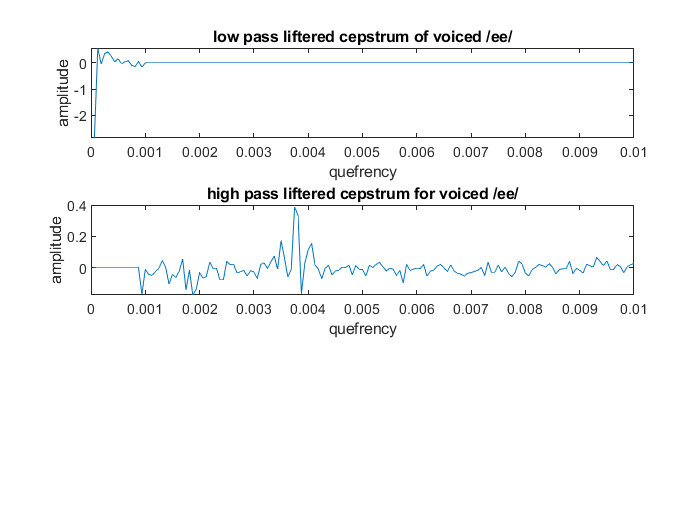

L_low=zeros(1,length(y_ee_lift));%for defining liftering window
L_low(1:15)=1 ;%Liftering window
y_ee_lowpass =real(y_ee_lift.*(L_low.')) ;
t_ee_lowpass = (1:length(y_ee_lowpass))/fs;


%High-time liftering
L_high(15:length(y_ee_lift))=1 ;
y_ee_highpass =real(y_ee_lift.*(L_high.')) ;
t_ee_highpass = (1:length(y_ee_highpass))/fs;

%ploting low pass liftering and high pass liftered cepstrum for voiced /ee/
figure ;
subplot(3,1,1)
plot(t_ee_lowpass,y_ee_lowpass);
xlabel('quefrency');
ylabel('amplitude');
title('low pass liftered cepstrum of voiced /ee/')

subplot(3,1,2)
plot(t_ee_highpass,y_ee_highpass);
xlabel('quefrency');
ylabel('amplitude');
title('high pass liftered cepstrum for voiced /ee/')

%low-time liftering
y_ss_lift=y_ss_cep(1:length(y_ss_cep)/2);%as cepstrum is symmetric we are taking half of the cepstral coefficiets 

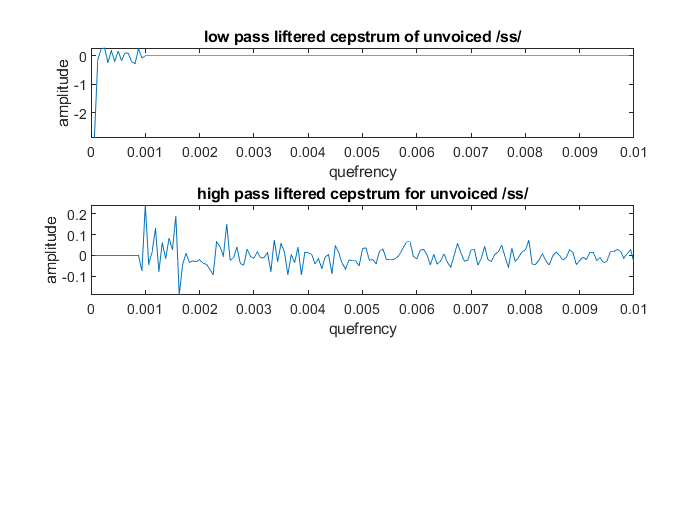

L_low=zeros(1,length(y_ss_lift));%for defining liftering window
L_low(1:15)=1 ;%Liftering window
y_ss_lowpass =real(y_ss_lift.*(L_low.')) ;
t_ss_lowpass = (1:length(y_ss_lowpass))/fs;


%High-time liftering
L_high(15:length(y_ss_lift))=1 ;
y_ss_highpass =real(y_ss_lift.*(L_high.')) ;
t_ss_highpass = (1:length(y_ss_highpass))/fs;

%ploting low pass liftering and high pass liftered cepstrum for voiced /ee/
figure ;
subplot(3,1,1)
plot(t_ss_lowpass,y_ss_lowpass);
xlabel('quefrency');
ylabel('amplitude');
title('low pass liftered cepstrum of unvoiced /ss/')

subplot(3,1,2)
plot(t_ss_highpass,y_ss_highpass);
xlabel('quefrency');
ylabel('amplitude');
title('high pass liftered cepstrum for unvoiced /ss/')

2. Write about how you used Low-Time Liftering and High-Time Liftering for extracting the above components.

1) The low-time liftering window used for extracting vocal tract characteristics : 

where Lc is the cut off length of the liftering window and N/2 is half the total length of the cepstrum.

a) To obtain vocal tract charasteristics : multiply the cepstrum c(n) with the low-time liftering window

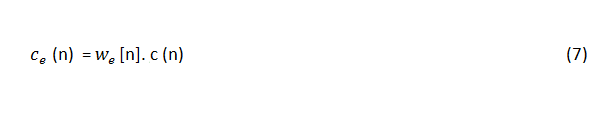

b) Apply DFT on the low-time liftered sequence. This takes to its log magnitude spectrum which is the vocal tract spectrum of the given short term speech.

2) The excitation characteristic are obtained through a **high time liftering operation** using the following window :

a) The excitation characteristics are obtained by multiplying high time liftering window with the cepstrum: 

**C. Pitch estimation by cepstral analysis:**

- In the case of the voiced segment, estimate the pitch of the voiced speech segment using the cepstral analysis. Explain your procedure.

**High-time liftering process **for pitch estimation.

Procedure is to find the peaks in the high pass liftered cepstrum : because the location of peak gives pitch period in quefrequency samples.

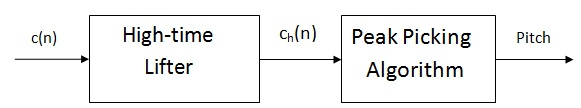

Pitch can be estimated as the instant corresponds to the significant peak in the high-time liftered cepstrum.

Pitch period is the  time instant corresponding to the largest peak in the high-time liftered cepstrum.

The reciprocal of the pitch interval multiplied by the sampling frequency gives the pitch frequency of the analysis speech frame.

% Pitch estimation
[M,I]=max(y_ee_highpass);   % finding the peak in high pass liftered cepstrum
pitch_period_voiced = I

pitch_period_voiced = 60

Fo = (1/I)*fs ;            % converting pitch period in samples to frequency in hz
Pitch_frequency_voiced = Fo

Pitch_frequency_voiced = 266.6667

**D. Formant estimation by cepstral analysis:**

- Using liftered cepstrum, estimate the frequencies of the first three resonances of the vocal tract of the voiced speech frame.. Explain your procedure. Plot the log magnitude spectrum that shows the formant information (while not having the excitation information). 

- Repeat the above for the unvoiced speech frame.

**Theory and Procedure:**

Formant estimation/location can be computed from the vocal-tract spectrum.

The formant locations can be estimated by picking the peaks from the smooth vocal tract spectrum.

% Formant estimation
%for voiced frame /ee/
y_ee_cep_coeff = y_ee_lowpass(1:15);  % taking cepstral coefficients from low pass liftered cepstral seq
dfty_ccoeff_ee = abs(fft(y_ee_cep_coeff,16000));
dfty_ccoeff_ee = real(dfty_ccoeff_ee(1:8000));

%for unvoiced frame /ss/
y_ss_cep_coeff = y_ss_lowpass(1:15);  % taking cepstral coefficients from low pass liftered cepstral seq
dfty_ccoeff_ss = abs(fft(y_ss_cep_coeff,16000));
dfty_ccoeff_ss = real(dfty_ccoeff_ss(1:8000));

f1 = (1:16000).*(fs/16000); 

% peak picking algorithm
% for voiced
k = 1;
for i=2:length(dfty_ccoeff_ee)-1
    if (dfty_ccoeff_ee(i-1)< dfty_ccoeff_ee(i)) & (dfty_ccoeff_ee(i+1)< dfty_ccoeff_ee(i))
        formant_mag(k) = dfty_ccoeff_ee(i);
        formant(k)=i;
        k = k+1;        
    end
end
formant

formant =         1300        2346        4347        5640        6865


% for unvoiced
k = 1;
for i=2:length(dfty_ccoeff_ss)-1
    if (dfty_ccoeff_ss(i-1)< dfty_ccoeff_ss(i)) & (dfty_ccoeff_ss(i+1)< dfty_ccoeff_ss(i))
        formant_mag_ss(k) = dfty_ccoeff_ss(i);
        formant_ss(k)=i;
        k = k+1;      
    end
end
formant_ss

formant_ss =         1484        2859        4227        5585        6871


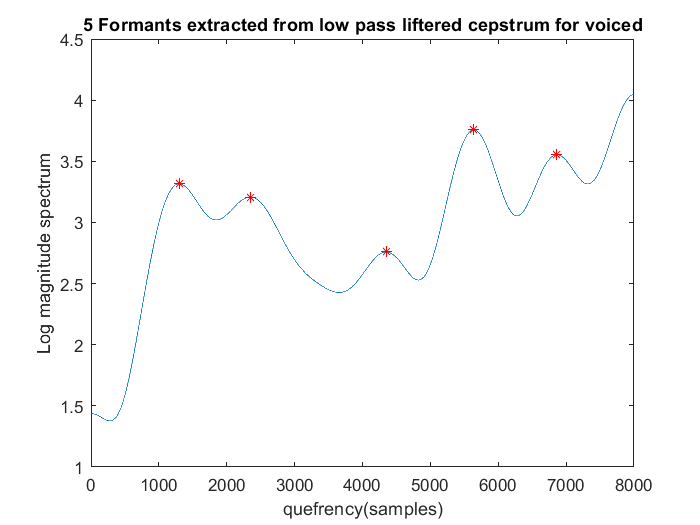


figure;
plot(f1(1:8000),dfty_ccoeff_ee);
hold on;
plot(formant,formant_mag,'r*');
hold off;
xlabel('quefrency(samples)');
ylabel('Log magnitude spectrum');
title('5 Formants extracted from low pass liftered cepstrum for voiced')

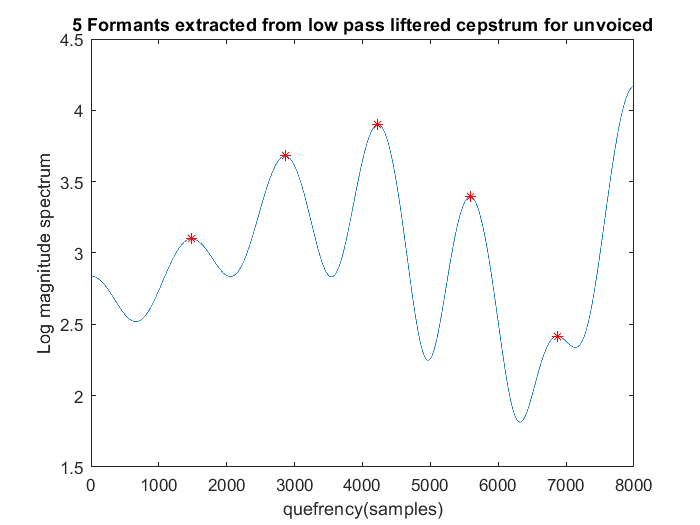


figure;
plot(f1(1:8000),dfty_ccoeff_ss);
hold on;
plot(formant_ss,formant_mag_ss,'r*');
hold off;
xlabel('quefrency(samples)');
ylabel('Log magnitude spectrum');
title('5 Formants extracted from low pass liftered cepstrum for unvoiced')

Function:

function [freq,Y] = mag_spec(y,fs)
N=length(y);% length of sound /a/
N1=2^nextpow2(N);
freq=fs*(0:N1/2-1)/N1; %Frequency axis for s
Y = fft(y,N1);
Y = Y(1:N1/2);
end
